**Procesamiento de imágenes 2021 -1**

# **Taller 3: Filtros espaciales.**

**Nombres**: Inserta aquí tu nombre | **Códigos**: Inserta aquí tu código.

Con el desarrollo del taller número 3 correspondiente a los** filtros espaciales**, podrás obtener resultados como los ilustrados a continuación:

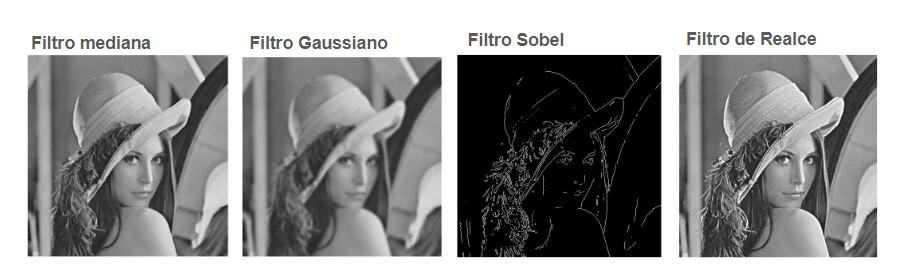

## **Recomendaciones para el desarrollo:**

- Construir un **banco de imágenes de ejemplo **para las pruebas, incluir diferentes tipos de imágenes.

- Dar prioridad a realizar **operaciones matemáticas y álgebra lineal** antes de usar estrategias puramente algorítmicas.

- Cada una de las operaciones se debe registrar en** funciones** y deben estar desacopladas y  pensadas para reutilizar código, con el fin de promover estrategias de **vectorización, paralelización, optimización en la codificación**, claridad y especialización de funciones.

- **No se podrán usar las funciones nativas de matlab** para generación de máscaras y aplicación de filtros, sin embargo te invitamos a comparar los resultados con las funciones fspecial y imfilter.

- Optimizar el número de líneas de código y** documentar las funciones y las líneas de código.**

- Utilizar **nombres de variables coherentes y descriptivos,**  evitar el uso de diminutivos.

- Siguir buenas prácticas en programación según estándares ampliamente reconocidos. [Ejemplo de algunas](https://springerlab.org/qmbc/files/MATLAB_Good_Programming_Practices.pdf).

## 1. Realizar una implementación genérica para realizar filtros espaciales, a partir de una imagen y una máscara cuadrada de dimensión nxn.

## 2. Implementar el algoritmo para calcular automáticamente las máscaras de un filtro gaussiano 

### a. Usando la ecuación descriptiva de la campana de gauss en 2D

###  b. Usando la aproximación de pascal.

Calcula y muestra el nivel del triángulo de pascal creado propiamente.

    nivel= pascal(n)

Crea y muestra la máscara Gaussiana creada a partir del nivel anterior.

    mascara_gauss=gaussiana(n)

## 3.  Realizar el filtrado gaussiano de algunas imágenes y comparar los resultados, con los dos métodos anteriores.

Crea tu banco de imágenes y lee la imagen a trabajar en este punto.

   %I=imread();

Aplica diferentes máscaras gaussiana a la imagen con la función propia de filtrado  

   %... 
   imshowpair(Inormal, IGaussiana)

## 4. Implementar un filtro mediana en una vecindad de nxn.

Aplica el filtro de la mediana a la imagen

    %...

Mostrar los resultados

    %... 
    imshowpair(Inormal, Imediana)
    imshowpair(IGaussiana, Imediana)

## 5. Implementar un filtro de detección de bordes usando las máscaras de Sobel, Prewitt y Roberts.

Calcular el gradiente

[Imag,Iang]=gradiente(I,'sobel');
%....

Realiza los cálculos para graficar la magnitud y el ángulo del gradiente.

Muestra tus resultados y comparaciones.

    imshowpair(Inormal, Imag)
    %.....

## 6. Implementar un filtro de realce usando un filtro de desenfoque.

Primero aplica el filtro gaussiano a tu imagen.

Aplica el proceso para encontrar la imagen de realce que sustentaste anteriormente.

## 7. Conclusiones 

## **Desarrollo de funciones**

function imagen = filtrando(I,m)
%Esta función realiza la aplicación de un filtro espacial
%   I       es la imagen original.
%   m       es la máscara por aplicar.
%   imagen  es la imagen filtrada.

    %Desarrolla las operaciones pertinentes.
end

function [Gm,Ga] = gradiente(I,metodo)
%Esta función realiza la aplicación de un filtro espacial
%   I            imagen original.
%   metodo       'sobel','roberts','prewitt','sobel45', ...
%   Ga      magnitud del gradiente
%   Gm      angulo del gradiente

    %Desarrolla las operaciones pertinentes.
end

function imagen = realce(I)
%Esta función realiza la aplicación de un filtro espacial
%   I       es la imagen original.
%   imagen  es la imagen realzada.

    %Desarrolla las operaciones pertinentes.
end

function nivel= pascal(n)
%Esta función encuentra el vector nivel del tríangulo de pascal.
%   n       es el orden deseado.
%   nivel   es el vector resultante.

    %Desarrolla las operaciones pertinentes.
end

function mascara= gaussiana(n, metodo, sigma)
...Genera la máscara de Gauss a partir de un orden deseado.
%   n           es el orden deseado.
%   metodo      'pascal', 'ecuación'
%   sigma       varianza (método por ecuación)
%   mascara     es la matriz resultante.
    
    %Desarrolla las operaciones pertinentes.
    
end

### **Recursos**

- [https://la.mathworks.com/help/matlab/matlab_prog/vectorization.html](https://la.mathworks.com/help/matlab/matlab_prog/vectorization.html)

- [https://la.mathworks.com/help/images/image-enhancement-and-restoration.html](https://la.mathworks.com/help/images/image-enhancement-and-restoration.html)

### **¿Necesitas ayuda?**

Si necesitas ayuda, no dudes en comunicarte en los horarios de atención de la docente, asistir a los espacios de monitoría, preguntar por el grupo de discord o escribirle al monitor de la clase.

- Horario de atención estudiantes docente: [https://docs.google.com/spreadsheets/d/1FKccsDfxhM28CFQEyFDzGnX-NBKmluMUsp7G2K69cVU/edit#gid=1274028078](https://docs.google.com/spreadsheets/d/1FKccsDfxhM28CFQEyFDzGnX-NBKmluMUsp7G2K69cVU/edit#gid=1274028078)

- Horario de monitoría: MARTES 17h - 18h & VIERNES 14h - 15h | Link: [https://meet.google.com/cqs-bfyo-mhk](https://meet.google.com/cqs-bfyo-mhk)

- Grupo de discord: [https://discord.gg/DMptHwFQfr](https://discord.gg/DMptHwFQfr)

- Correo monitor: est.jean.polo@unimilitar.edu.co